# FastFlow_Train

#### **Fred liu 2023.07.17**

**update 2024.02.15**

2023a之後的版本更新了三種異常偵測的演算法，分別是：

**Fully convolitional data description(FCDD)**

**FastFlow**

**PatchCore**

詳細資訊可以在此連結中找到：[Getting Started with Anomaly Detection Using Deep Learning](https://www.mathworks.com/help/vision/ug/getting-started-with-anomaly-detection-using-deep-learning.html)

### Download DataSet VisA

使用Dataset :  [VisA Visual Inspection Dataset](https://github.com/amazon-science/spot-diff)

Only load normal sample

Normaldatadir = "D:\Fred\MATLAB_Project(myself)\AnomalyDetection\VisA_20220922\VisA_20220922\pcb4\Data\Images\Normal";
Anomalydatadir = "D:\Fred\MATLAB_Project(myself)\AnomalyDetection\VisA_20220922\VisA_20220922\pcb4\Data\Images\Anomaly";

### 載入資料與資料分割(Load Data & Splits Dataset )

NormaldsPCB = imageDatastore(Normaldatadir,IncludeSubfolders=true,LabelSource="foldernames");
summary(NormaldsPCB.Labels)

     Normal      1005 


AnomalydsPCB = imageDatastore(Anomalydatadir,IncludeSubfolders=true,LabelSource="foldernames");
summary(AnomalydsPCB.Labels)

     Anomaly      100 


分割少量資料做訓練

%[dsTrain,dsVal,dsTest] = splitAnomalyData(dsPCB,"Anomaly");
[NormaldsPCB_10,NormaldsPCB_90] = splitEachLabel(NormaldsPCB,0.1)

NormaldsPCB_10 =   ImageDatastore with properties:

                       Files: {
                              ' ...\VisA_20220922\VisA_20220922\pcb4\Data\Images\Normal\0000.JPG';
                              ' ...\VisA_20220922\VisA_20220922\pcb4\Data\Images\Normal\0001.JPG';
                              ' ...\VisA_20220922\VisA_20220922\pcb4\Data\Images\Normal\0002.JPG'
                               ... and 98 more
                              }
                     Folders: {
                              ' ...\AnomalyDetection\VisA_20220922\VisA_20220922\pcb4\Data\Images\Normal'
                              }
                      Labels: [Normal; Normal; Normal ... and 98 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                    

NormaldsPCB_90 =   ImageDatastore with properties:

                       Files: {
                              ' ...\VisA_20220922\VisA_20220922\pcb4\Data\Images\Normal\0101.JPG';
                              ' ...\VisA_20220922\VisA_20220922\pcb4\Data\Images\Normal\0102.JPG';
                              ' ...\VisA_20220922\VisA_20220922\pcb4\Data\Images\Normal\0103.JPG'
                               ... and 901 more
                              }
                     Folders: {
                              ' ...\AnomalyDetection\VisA_20220922\VisA_20220922\pcb4\Data\Images\Normal'
                              }
                      Labels: [Normal; Normal; Normal ... and 901 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                  

### 顯示資料庫影像

正常影像

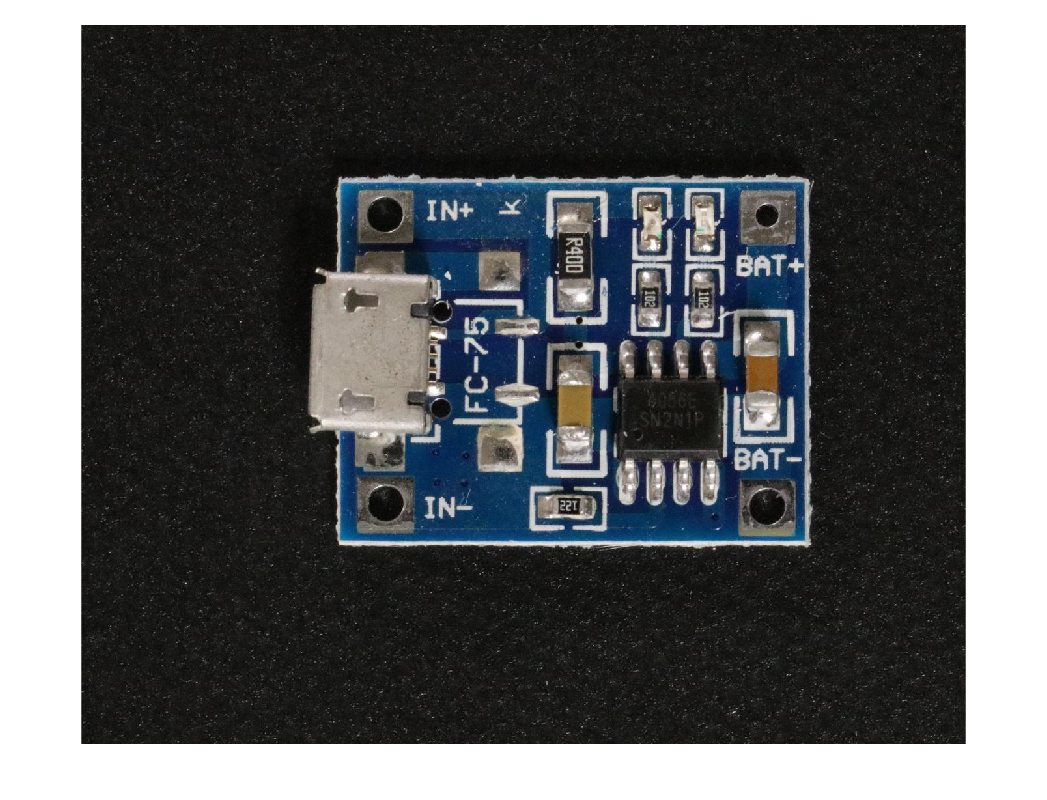

figure,imshow(preview(NormaldsPCB))

異常影像

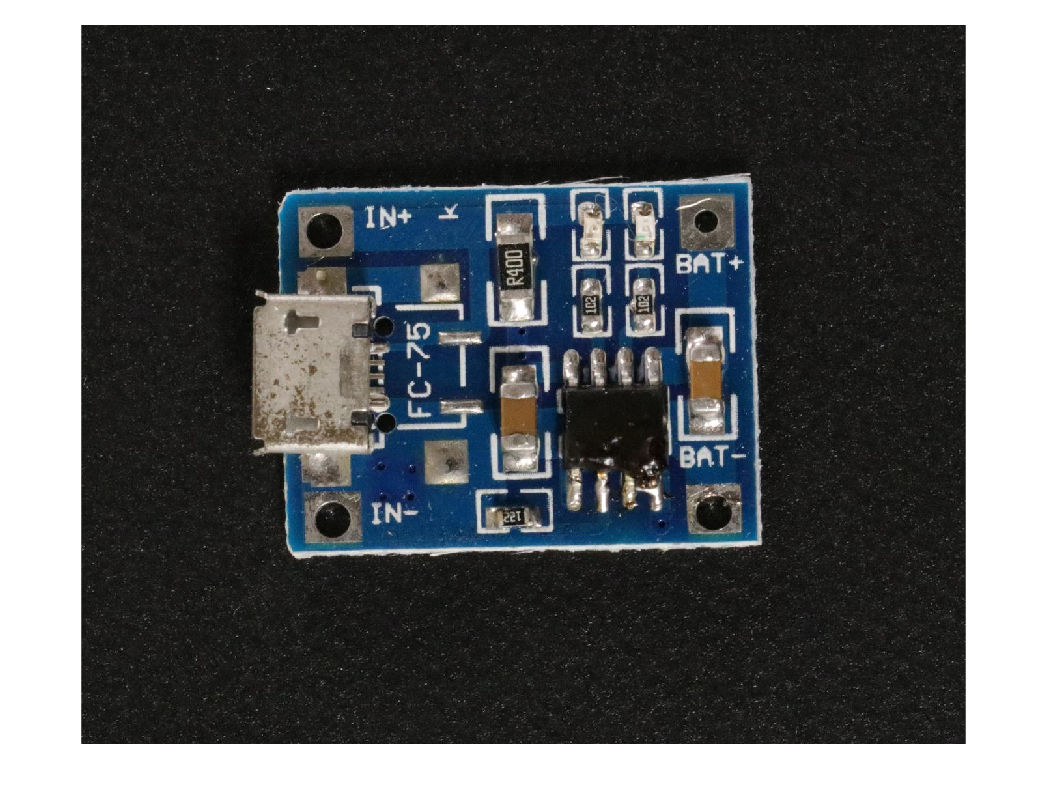

figure,imshow(preview(AnomalydsPCB))

### 資料前處理(resize and preview)

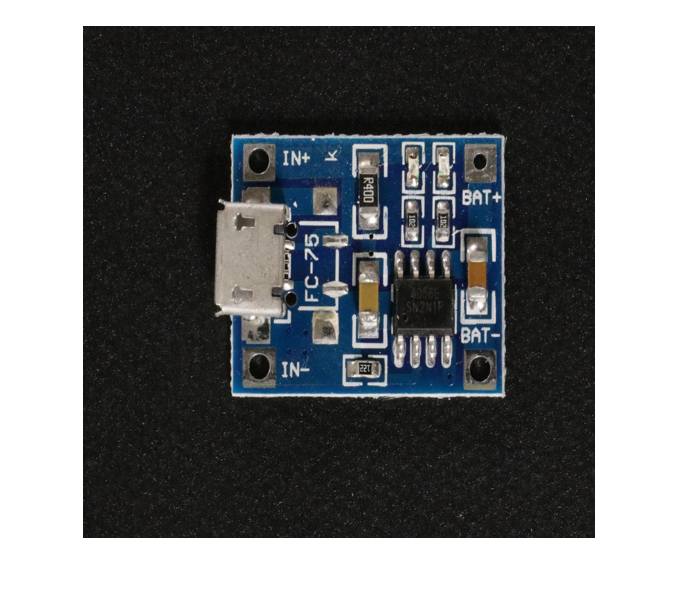

resizeFcn = @(x) imresize(x,OutputSize=[512 512]);
NormaldsPCB_10 = transform(NormaldsPCB_10,resizeFcn);
figure,imshow(preview(NormaldsPCB_10))

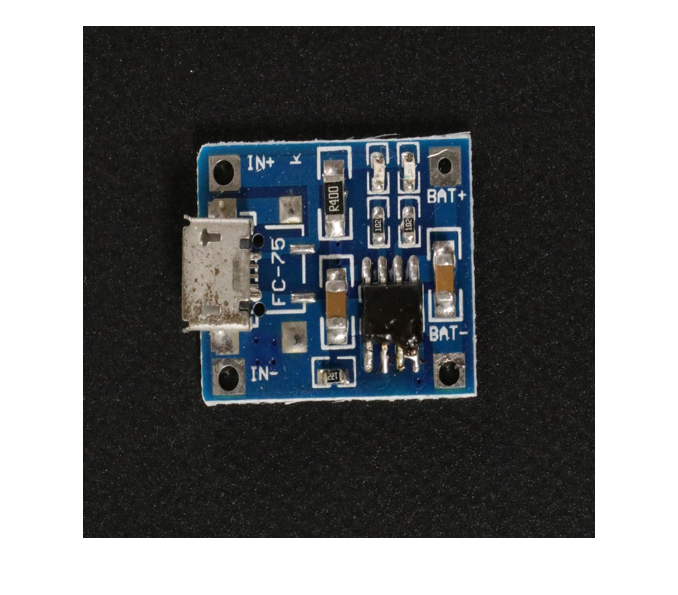

resizeFcn = @(x) imresize(x,OutputSize=[512 512]);
AnomalydsPCB = transform(AnomalydsPCB,resizeFcn);
figure,imshow(preview(AnomalydsPCB))

### 建立模型

建立fastFlowAnomaly Detector

fastFlow = fastFlowAnomalyDetector

fastFlow =   fastFlowAnomalyDetector with properties:

      Threshold: []
          State: []
     Learnables: [150×3 table]
         Layers: [222×1 nnet.cnn.layer.Layer]
     InputNames: {'data'}
    OutputNames: {'AffineScaleAndShiftScale1Step8/Z'  'AffineScaleAndShiftScale1Step8/logdet'  'AffineScaleAndShiftScale2Step8/Z'  'AffineScaleAndShiftScale2Step8/logdet'  'AffineScaleAndShiftScale3Step8/Z'  'AffineScaleAndShiftScale3Step8/logdet'}


### 切割驗證資料集(FastFlow中暫時不切)

%dsValGoodIdx = dsVal.UnderlyingDatastores{1}.Labels == "Normal";
%dsValGood = subset(dsVal,dsValGoodIdx);
%dsValBad = subset(dsVal,~dsValGoodIdx);

### 訓練與參數設定

設定相關訓練的參數

[`detector = trainFastFlowAnomalyDetector(normalData,detectorIn,options)`](https://127.0.0.1:31515/static/help/vision/ref/trainfastflowanomalydetector.html?snc=RQNRIH&searchsource=mw&container=jshelpbrowser#d124e290693)

options = trainingOptions("adam", ...
   InitialLearnRate = 1e-2, ...
    BatchNormalizationStatistics="moving", ...
    MaxEpochs=50, ...
    VerboseFrequency=4, ...
    MiniBatchSize=128, ...
    Shuffle="every-epoch", ...
    Plots="none");

detector_FastFlow = trainFastFlowAnomalyDetector(NormaldsPCB_10,fastFlow,options)

Computing Input Normalization Statistics.
 
    Epoch    Iteration    TimeElapsed    LearnRate    TrainingLoss
    _____    _________    ___________    _________    ____________
      4          4         00:01:21        0.01        7.5136e+09 
      8          8         00:02:38        0.01       -1.0908e+08 
     12         12         00:03:57        0.01       -1.2481e+08 
     16         16         00:05:19        0.01       -1.0351e+08 
     20         20         00:06:40        0.01       -1.3487e+08 
     24         24         00:07:59        0.01       -1.3888e+08 
     28         28         00:09:17        0.01       -1.4107e+08 
     32         32         00:10:35        0.01       -1.4331e+08 
     36         36         00:11:54        0.01       -1.4511e+08 
     40         40         00:13:14        0.01  

detector =   fastFlowAnomalyDetector with properties:

      Threshold: []
          State: []
     Learnables: [150×3 table]
         Layers: [222×1 nnet.cnn.layer.Layer]
     InputNames: {'data'}
    OutputNames: {'AffineScaleAndShiftScale1Step8/Z'  'AffineScaleAndShiftScale1Step8/logdet'  'AffineScaleAndShiftScale2Step8/Z'  'AffineScaleAndShiftScale2Step8/logdet'  'AffineScaleAndShiftScale3Step8/Z'  'AffineScaleAndShiftScale3Step8/logdet'}


### 測試影像

載入單張影像進行異常偵測測試

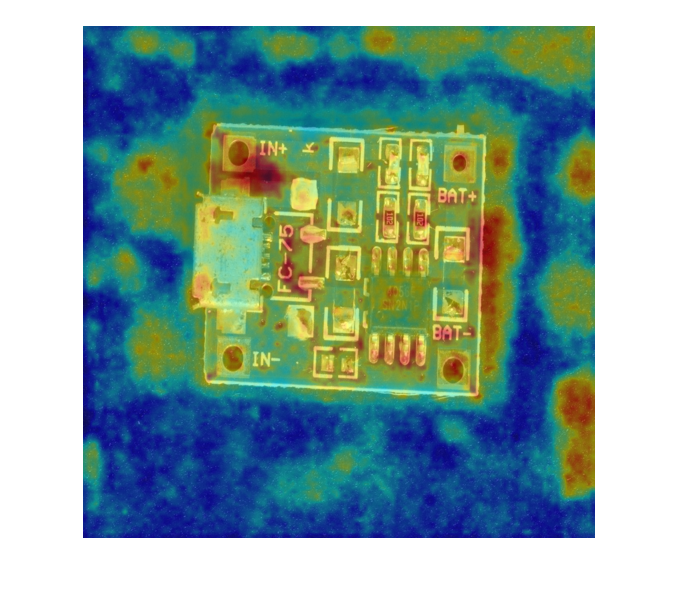

AnomalyImage = imread("D:\Fred\MATLAB_Project(myself)\AnomalyDetection\VisA_20220922\VisA_20220922\pcb4\Data\Images\Anomaly\060.JPG");
%AnomalyImage = imread("D:\Fred\MATLAB_Project(myself)\AnomalyDetection\VisA_20220922\VisA_20220922\pcb4\Data\Images\Normal\0012.JPG");
AnomalyImage = imresize(AnomalyImage,[512 512]);
displayRange = [-1,162];
map2 = anomalyMap(detector_FastFlow,AnomalyImage);
%image2 = (anomalyMapOverlay(AnomalyImage,map2,MapRange=displayRange,Blend="equal"));
image2 = (anomalyMapOverlay(AnomalyImage,map2,Blend="equal"));
figure,imshow(image2)

## 資料庫檢測

Testdatadir = "D:\Fred\MATLAB_Project(myself)\AnomalyDetection\VisA_20220922\VisA_20220922\pcb4\Data\Images\";
TestdsPCB = imageDatastore(Testdatadir,IncludeSubfolders=true,LabelSource="foldernames");
summary(TestdsPCB.Labels)
resizeFcn = @(x) imresize(x,OutputSize=[512 512]);
TestdsPCB = transform(TestdsPCB,resizeFcn);
figure,imshow(preview(TestdsPCB))

gtLabels = TestdsPCB.UnderlyingDatastores{1,1}.Labels;
anomalyLabels = "Anomaly";
predScores = predict(detector_FastFlow,TestdsPCB);

View the anomaly detection results.

[T,roc] = anomalyThreshold(gtLabels,predScores,anomalyLabels)